## Cvičení 7: - Integrály

Určité integrály:


$$\int_a^b f\left(x\right)=\lim_{h\;\to \;0} \left(\sum_{i\;=\;a}^b f\left(i\right)*h\right)\;$$



$$f\left(x\right)=\sin \left(x\right)$$



$$\int_0^{2\pi } f\left(x\right)={\left\lbrack -\cos \left(x\right)\right\rbrack \;}_0^{2\pi } =-\cos \left(0\right)--\cos \left(2\pi \right)=1-1=0$$


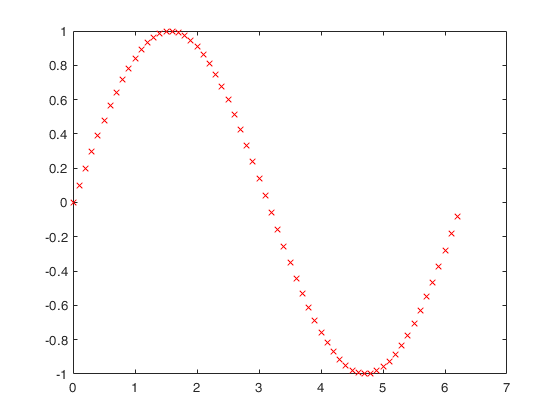

h = 0.1; % 0.01
x = 0:h:2*pi;
y = sin(x);
plot(x,y,'xr');


S = 0;

for i = 1:length(y)
   S = S + (h * y(i)); 
end

S

S =     -6.994492302849330e-04


Nějaká hezká funkce:

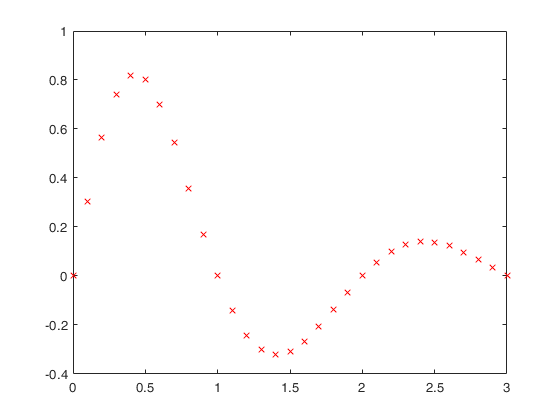

h = 0.1;
x = 0:h:3;
y = sin(pi.*x)./(x.^2 + 1);

plot(x,y,'xr');


S = 0;

for i = 1:length(x)
   S = S + (h * y(i)); 
end

S

S =    0.389786750005237


Úkol vytvořit funkci integrálu!!:

h = 0.1; % 0.001
a = 0;
b = 3;
f = @(in) sin(pi*in)./(in.^2 + 1);
y = f(x);

plot(x,y,'xr');


integruj(f,x(1),x(end),h)

ans =    0.389786750005237


% integral(f,x(1),x(end))

Udělat výpočet obsahu kruhu:

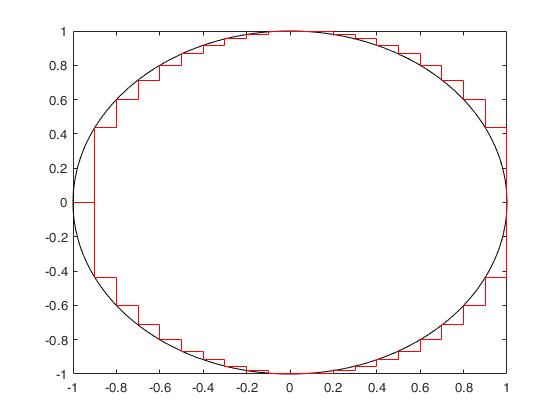

f = @(x) sqrt(1 - x.^2);
x = -1:0.001:1;
y = f(x);

plot(x,y,'k');
hold on;
plot(x,-y,'k');

h = 0.1;
a = -1;
b = 1;

x = a:h:b;
y = f(x);

stairs(x,y,'r'); 
hold on;
stairs(x,-y,'r');


format("long");
2*(integruj(f,a,b,h))

ans =    3.104518326248318


pi

ans =    3.141592653589793


Úkol: Vytvořit funkci pro výpočet integrálu:

function [S] = integruj(func,a,b,h)

x = a:h:b;

S = 0;

for i = 1:length(x)
   S = S + (h * func(x(i))); 
end

end